savenam = foldernam + 'Data\1-CCRN-1-cat_descend_2_1_straightIC_500_06-Dec-2023.mat'

savenam = "Evolution - Praful\Data\1-CCRN-1-cat_descend_2_1_straightIC_500_06-Dec-2023.mat"

load(savenam)
PS_traj_21 = PS_traj;
savenam = foldernam + 'Data\1-CCRN-1-cat_descend_3_1_straightIC_500_05-Dec-2023.mat'
load(savenam)
PS_traj_31 = PS_traj;

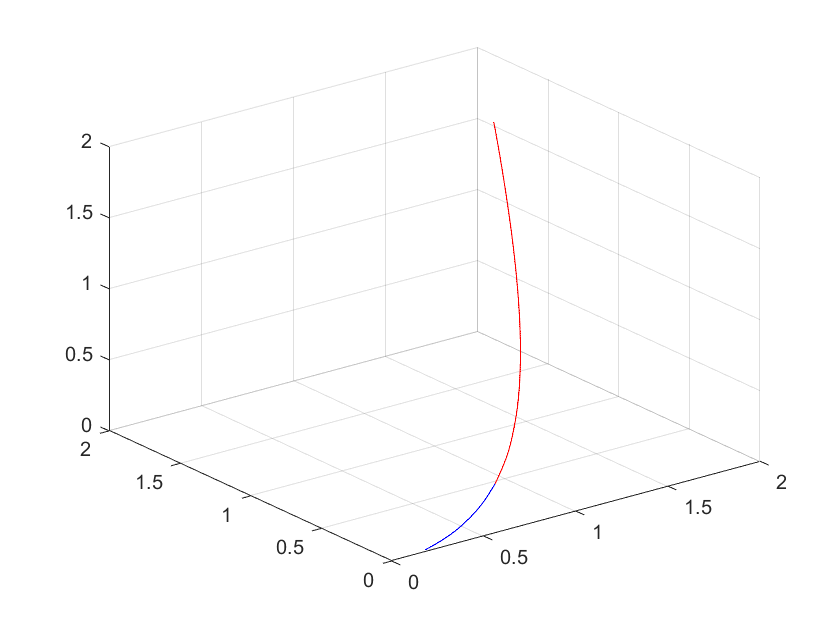

figure()
PS_traj = PS_traj_21;
plot3(PS_traj(:,1),PS_traj(:,2),PS_traj(:,3),'b')
hold on
PS_traj = PS_traj_31;
plot3(PS_traj(:,1),PS_traj(:,2),PS_traj(:,3),'r')
hold off
grid on

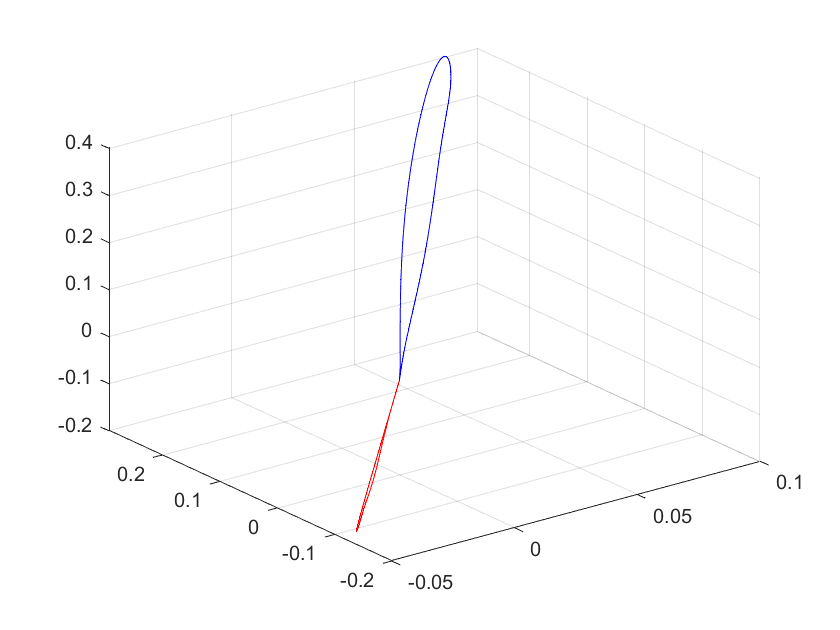

figure()
PS_traj = PS_traj_21;
plot3(PS_traj(:,4),PS_traj(:,5),PS_traj(:,6),'b')
hold on
PS_traj = PS_traj_31;
plot3(PS_traj(:,4),PS_traj(:,5),PS_traj(:,6),'r')
hold off
grid on

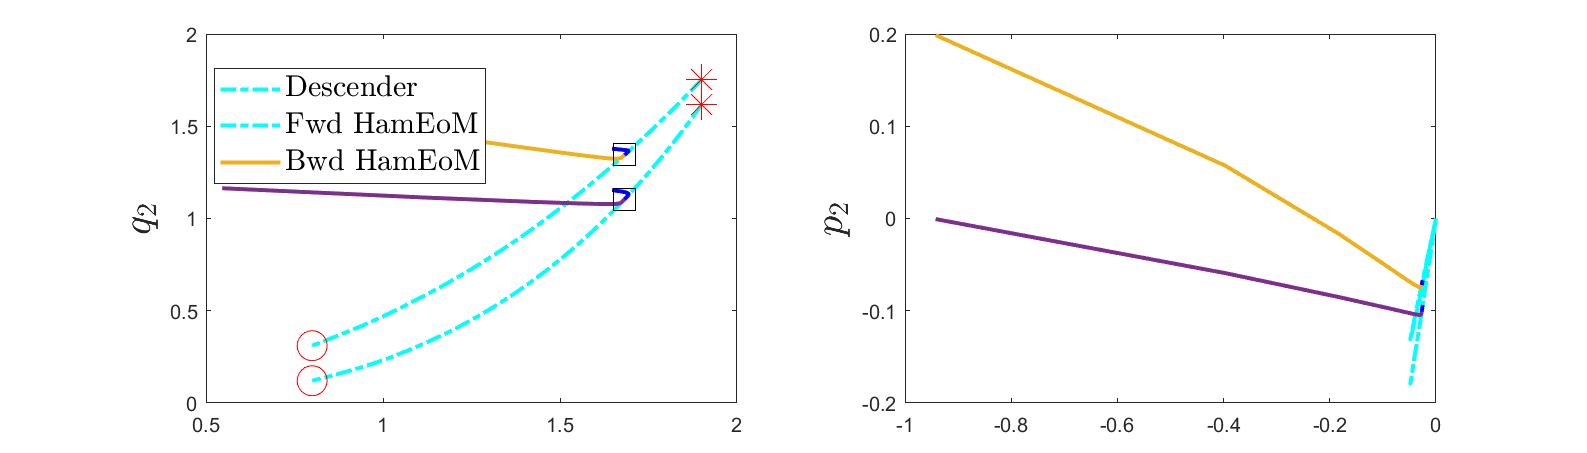

a = 2.1955

a = ham_closest_approach(PS_traj,S_traj,t_traj,...
    dHamdp_fun, dHamdq_fun, "asdf",0,'asf')

%graph of CRN
rxn_rate

rxn_rate =     1.0000    2.0000    0.1476
    2.0000    1.0000    1.0000
    3.0000    4.0000    1.0000
    4.0000    3.0000    2.0600
    5.0000    6.0000    1.0000
    6.0000    5.0000    2.0600
    4.0000    7.0000    2.9000
    7.0000    4.0000    1.0000


%input and output stoichiometric matrices
inp_stoich = comp_vec(rxn_rate(:,1),:)

inp_stoich =      0     0     0
     1     0     0
     2     0     0
     0     1     0
     1     1     0
     0     0     1
     0     1     0
     1     1     0


out_stoich = comp_vec(rxn_rate(:,2),:)

out_stoich =      1     0     0
     0     0     0
     0     1     0
     2     0     0
     0     0     1
     1     1     0
     1     1     0
     0     1     0


%monomials for reactions
rxn_inp = {};
for i = 1:size(rxn_rate,1)
    y_in = comp_vec(rxn_rate(i,1),:)';
    rxn_inp{end+1} = rxn_rate(i,3)*prod(q.'.^y_in);
end
celldisp(rxn_inp)

 
rxn_inp{1} =
 


$$\frac{369}{2500}$$

 
 
rxn_inp{2} =
 


$$q_{1}$$

 
 
rxn_inp{3} =
 


$${q_{1}}^{2}$$

 
 
rxn_inp{4} =
 


$$\frac{103\,q_{2}}{50}$$

 
 
rxn_inp{5} =
 


$$q_{1}\,q_{2}$$

 
 
rxn_inp{6} =
 


$$\frac{103\,q_{3}}{50}$$

 
 
rxn_inp{7} =
 


$$\frac{29\,q_{2}}{10}$$

 
 
rxn_inp{8} =
 


$$q_{1}\,q_{2}$$